# AAE 451 Senior Design: Hover Roll Control 

 Author: Tomoki Koike

## Problem Formulation

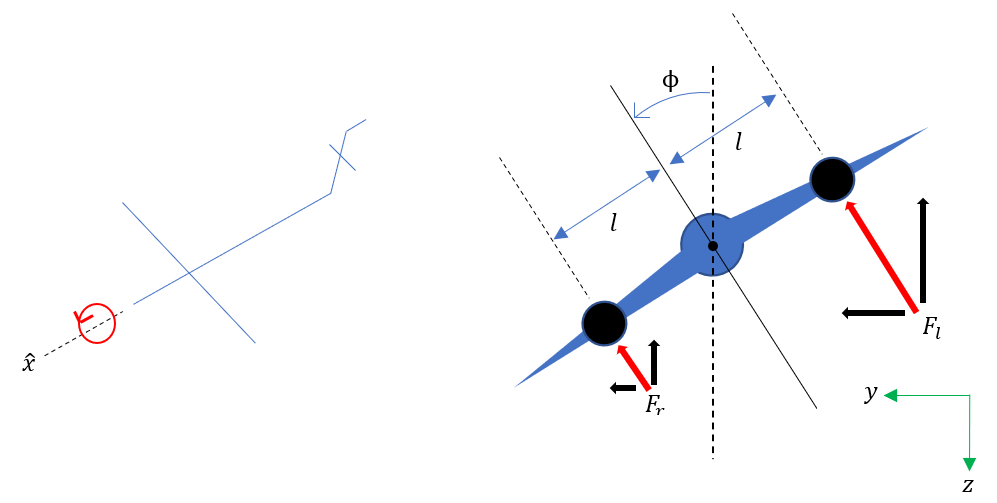

**Fig. 1.**

The intial step is to model the dynamical system. In order to do this we will consider the translational motion in the y and z direction as well as the rotational motion along the longitudinal axis. Keeping in the mind that the translational motion is with respect to the center of gravity (CG) we can formulate the system equations as follows.


$$m\ddot{y} +c_y \dot{y} =\sum F_y =F_r \sin \phi +F_{l\;} \sin \phi$$



$$m\;\ddot{z} +c_z \;\dot{z} =\sum F_z ={-F}_r \;\cos \phi -F_l \;\cos \phi +\mathrm{mg}$$



$$M_{x\;} =J_{\textrm{xx}} \;\ddot{\phi} =l\left(F_l -F_r \right)$$


With this we also consider the fan model as a first order transfer function.


$$G_{\mathrm{fan}} =\frac{F}{u_{\mathrm{fan}} }=\frac{F_{\max } }{\frac{s}{\tau }+1}$$


Let the inputs for this system be 


$$u_1 :=F_l \;,u_2 \;:=F_r$$


Now we can rewrite the equation as 


$$\ddot{y} =-\frac{c_y }{m}\dot{y} +\frac{u_1 \;\sin \phi }{m}+\frac{u_2 \;\sin \phi }{m}$$



$$\ddot{z} =-\frac{c_z }{m}\;\dot{z} -\frac{u_1 \cos \phi }{m}-\frac{u_2 \;\cos \phi }{m}+g$$



$$\ddot{\phi} =\frac{l}{J_{\textrm{xx}} }u_1 -\frac{l}{J_{\textrm{xx}} }u_2$$


Defining the output as 


$$x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y\\
z\\
\phi \\
\dot{y} \\
\dot{z} \\
\dot{\phi} 
\end{array}\right\rbrack$$


### Linearization Analysis

First we will analyze this system by linearizing the system and checking the eigenvalues of the system matrix. 

Let the equilibrium conditions be,


$$y_e =0,z_e =0,\phi_e =0^{\;o} ,u_{1e} =u_{2e} =\frac{\textrm{mg}}{2}\;$$


and the linearization process is as follows 


$$\delta \ddot{y} =-\frac{c_y }{m}\delta \dot{y} +\frac{\sin \phi_e }{m}\delta u_1 +\frac{\cos \phi_e }{m}u_{1e} \;\delta \phi +\frac{\sin \phi_e }{m}\delta u_2 +\frac{\cos \phi_e }{m}u_{2e} \;\delta \phi$$



$$\delta \ddot{z} \;=-\frac{c_z }{m}\;\delta \dot{z} -\frac{\cos \phi_e }{m}\delta u_1 +\frac{\sin \phi_e }{m}u_{1e} \delta \phi -\frac{\cos \phi_e }{m}\delta u_2 +\frac{\sin \phi_e }{m}u_{2e} \delta \phi$$



$$\delta \ddot{\phi} =\frac{l}{J_{\textrm{xx}} }\delta u_1 -\frac{l}{J_{\textrm{xx}} }\delta u_2$$


This becomes 


$$\delta \ddot{y} =-\frac{c_y }{m}\delta \dot{y} +g\delta \phi$$



$$\delta \ddot{z} \;=-\frac{c_z }{m}\;\delta \dot{z} -\frac{\delta u_1 }{m}-\frac{\delta u_2 }{m}$$



$$\delta \ddot{\phi} =\frac{l}{J_{\textrm{xx}} }\delta u_1 -\frac{l}{J_{\textrm{xx}} }\delta u_2$$


The system matrix becomes


$$A=\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & -\frac{c_y }{m} & 0 & 0\\
0 & 0 & 0 & 0 & -\frac{c_z }{m} & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


For this system we can see that 


$$\textrm{eig}\left(A\right)=-\frac{c_y }{m}\;,-\frac{c_z }{m}\;,0,0,0,0\;\;$$


The linear system is shown to be proven, however, the nonlinear system is undetermined due to the eigenvalue at the origin. Thus, we will have to conduct a more sophisticated analysis for the nonlinear system.

The approach we are going to use is going to account for uncertainty and implement a robust controller for an uncertain parameter model [1].

### LMI Analysis

Before we design that we utilize the LMI toolbox to find an base value for the damping $c_y \;$and $c_z$. Say that we make the inputs a constant which is enough to maintain the stability 


$$u_{1\;} =u_2 =\frac{\textrm{mg}}{2}$$


 This implies that we can rewrite the system model to be 


$$\ddot{y} =-\frac{c_y }{m}\dot{y} +\mathrm{gsin}\phi$$



$$\ddot{z} =-\frac{c_z }{m}\dot{z} -\mathrm{gcos}\phi +g$$



$$\ddot{\phi} =0$$


From this we setup the system as 


$$\left\lbrack \begin{array}{c}
\dot{y} \\
\dot{z} \\
\dot{\phi} \\
\ddot{y} \\
\ddot{z} \\
\ddot{\phi} \\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccccccc}
0 & 0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & -\frac{c_y }{m} & 0 & 0 & 0\\
0 & 0 & 0 & 0 & -\frac{c_z }{m} & 0 & g\\
0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y\\
z\\
\phi \\
\dot{y} \\
\dot{z} \\
\dot{\phi} \\
1
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
g\\
0\\
0\\
0
\end{array}\right\rbrack \sin \phi +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
-g\\
0\\
0
\end{array}\right\rbrack \cos \phi$$


which is 


$$\dot{X} =\mathrm{AX}+B_1 g_1 \left(C_1 X\right)+B_2 g_2 \left(C_2 X\right)$$


such that 

$C_1 =\left\lbrack \begin{array}{ccccccc}
0 & 0 & 1 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \;$  and   $C_2 =\left\lbrack \begin{array}{ccccccc}
0 & 0 & 1 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$

and 

$g_1 \left(C_1 X\right)=\sin \phi$   and $g_2 \left(C_2 X\right)=\cos \phi$

Now, since 

$-1\le \sin \phi \le 1$  and   $-1\le \cos \phi \le 1\;$

we define 

$\gamma =1\;$ such that  $|\sin \phi \;|\le |\gamma \;|$ 

also defining $z_1 =C_1 X$ and $z_2 =C_2 X$ we can say that 

$\tilde{\phi} \left(z\right)=\left\lbrack \begin{array}{c}
\lambda_1 g_1 \left(\lambda_1^{-1} z_1 \right)\\
\lambda_2 g_2 \left(\lambda_2^{-1} z_2 \right)
\end{array}\right\rbrack$   where    $z=\left\lbrack \begin{array}{c}
z_1 \\
z_2 
\end{array}\right\rbrack$   with   $z_i \;\in R^{\textrm{Pi}}$

And thus, 


$$\dot{x} =\textrm{Ax}+\tilde{B} \tilde{\phi \;} \left(\tilde{C} X\right)$$


with

$\tilde{B} =\left\lbrack \begin{array}{cc}
\lambda_1^{-1} B_1  & \lambda_2^{-1} B_2 
\end{array}\right\rbrack \;\;$  and       $\tilde{C} =\left\lbrack \begin{array}{c}
\lambda_1 C_1 \\
\lambda_2 C_2 
\end{array}\right\rbrack$

From Theorem 19 of page 132 of cite [2], the system is globally exponentially stable about the origin with a Lypunov matrix P if the following matrix inequality is satisfied 


$$\textrm{PA}\;+A^T P+\sum_{i=1}^l \left(\mu_i^{-1} \gamma^2 {\textrm{PB}}_i B_i^T P+\mu C_i^T C_i \right)<0\;$$
 

The Schur complement while $\mu =\lambda^2 =1$ and $\gamma =1$ becomes


$$\left\lbrack \begin{array}{ccc}
\textrm{PA}+A^T P+C_1^T C_1 +C_2^T C_2  & {\textrm{PB}}_1  & {\textrm{PB}}_2 \\
B_1^T P & -I & 0\\
B_2^T P & 0 & -I
\end{array}\right\rbrack <0$$



$$0<P\;$$


% Housekeeping commands
clear all; close all; clc;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%  RUN THIS! %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read all the data necessary

addpath("../../../parameters/");
addpath("../sizing_code/");

% Load the excel sheet in the parameters folder to obtain constants 
T1 = readtable("catiaMeas.xlsx","Sheet","OGWingPosition");

S = readJSON2struct("output.json");
T2 = readtable("controlParameters.xlsx");

%%%%%%%%%%%%%%%%%%%%%%%%%%%%  RUN THIS! %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
g = 9.81;
m = T1.Mass_kg_(8);

consts.g = g;
consts.m = m;

echo off;
B1 = [0; 0; 0; g; 0; 0; 0];
B2 = [0; 0; 0; 0; -g; 0; 0];
C1 = [0 0 1 0 0 0 0];
C2 = C1; 

% Quadratic stability LMI of the problem 
% Setup LMI
setlmis([]);
% P matrix
p=lmivar(1, [7,1]);
cy = lmivar(1, [1, 1]);
cz = lmivar(1, [1, 1]);

A = [0 0 0 1 0 0 0;
     0 0 0 0 1 0 0;
     0 0 0 0 0 1 0;
     0 0 0 -cy/m 0 0 0;
     0 0 0 0 -cz/m 0 g;
     0 0 0 0 0 0 0;
     0 0 0 0 0 0 1];

% Equation 1
lmi1=newlmi;
lmiterm([lmi1,1,1,p],1,A,'s');  % PA + A'P
lmiterm([lmi1,1,1,0],(C1')*C1);  % C1'C1
lmiterm([lmi1,1,1,0],(C2')*C2);  % C2'C2
lmiterm([lmi1,1,2,p],1,B1);  % PB1
lmiterm([lmi1,1,3,p],1,B2);  % PB1
lmiterm([lmi1,2,2,0],-1);  % -I
lmiterm([lmi1,3,3,0],-1);  % -I
% Equation 2
lmi2=newlmi;
lmiterm([-lmi2,1,1,p],1,1);  % 0 < P
% Equation 3
lmi3 = newlmi;
lmiterm([-lmi3,1,1,cy],1,1);  % 0 < cy
% Equation 4
lmi4 = newlmi;
lmiterm([-lmi4,1,1,cz],1,1);  % 0 < cz
% Configure for solver
lmis = getlmis;
% Results
[tfeas, xfeas] = feasp(lmis);


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        2.225687
     2                        2.132240
     3                        2.132240
     4                        2.005554
     5                        2.005554
     6                        2.005554
     7                        2.004899
     8                        2.000138
     9                        2.000138
    10                        2.000138
    11                        2.000094
    12                        2.000002
    13                        2.000002
    14                        2.000002
    15                        2.000001
    16                        2.000000
    17                        2.000000
    18                        2.000000
    19                        2.000000
    20                        2.000000
    21

P = dec2mat(lmis,xfeas,p);

This gives us the result that the system is infeasible for quadratic stability.

Also we introduce the flexural rigidity constant into the system equation by approximating the wing to be a cantilever beam.

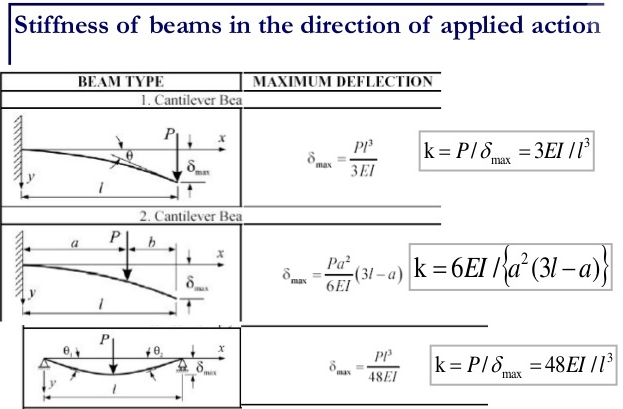

**Fig 2.**

Where we define 


$$g\times \textrm{WS}:=E\;\left\lbrack \frac{N}{m^2 }\right\rbrack ,\;I:=I_{\textrm{yy}} ,\;\;a:=l\;\left(\textrm{from}\;\textrm{Fig}\ldotp 1\ldotp \right),\;l:=\frac{b}{2}$$


where $b$ is the wing span and $\textrm{WS}$ is the wing loading, and $g$ is the gravitational acceleration. Thus,


$$k=\frac{3g\left(WS\right)I}{{\left(\frac{b}{2}\right)}^3 }$$


If we think of an overdamped case for a simple mass spring damper system, it is ideal to have the relation


$$c_z \;>\sqrt{4mk}=1\ldotp 5418e+4\;$$


Thus, we will assume that 


$$c_y \approx c_z$$


which alters the system equation to become 


$$\ddot{y} =-\frac{c_y }{m}\dot{y} -\frac{u_1 \;\sin \phi }{m}-\frac{u_2 \;\sin \phi }{m}$$



$$\ddot{z} =-\frac{k}{m}z-\frac{c_z }{m}\;\dot{z} +\frac{u_1 \cos \phi }{m}+\frac{u_2 \;\cos \phi }{m}+g$$



$$\ddot{\phi} =\frac{l}{J_{\textrm{xx}} }u_1 -\frac{l}{J_{\textrm{xx}} }u_2$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%  RUN THIS! %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
consts.WS = S.PerformanceInputs.WS;
consts.Iyy = T1.IoyG_kgxm2_(8);
consts.l = T2.Var2(1);
consts.b = S.GeometryOutput.b;
consts.k = 3 * consts.g * consts.WS * consts.Iyy / (consts.b)^3 / 8;

consts.cz = sqrt(4 * consts.m * consts.k) * 1.05;
consts.cy = consts.cz;

## Controller Design 

For this system, since we cannot measure the velocities and angular velocities of the states we will implement a LQG controller which is a combination of a LQE and LQR controller. The LQE is bascially a Kalman Filter (KF). Adding a PID controller that we could may inherit from our first design seems to be a robust control method [3]. However, to not overcomplicate the controller we will keep it as a LQG controller.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%  RUN THIS! %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Define necessary constants
k = consts.k;
cy = consts.cy;
cz = consts.cz;
m = consts.m;
g = consts.g;
l = consts.l;
% Obtain moment of inertias 
consts.Ixx = T1.IoxG_kgxm2_(8);
consts.Iyy = T1.IoyG_kgxm2_(8);
consts.Izz = T1.IozG_kgxm2_(8);
consts.Jxx = consts.Iyy + consts.Izz;
Jxx = consts.Jxx;

First we linearize the system about $y_e =0,z_e =0,\phi_e =0^{\;o} ,u_{1e} =u_{2e} =\frac{\textrm{mg}}{2}\;$


$$\delta \ddot{y} =-\frac{c_y }{m}\delta \dot{y} +g\delta \phi$$



$$\delta \ddot{z} \;=-\frac{k}{m}\delta z-\frac{c_z }{m}\;\delta \dot{z} -\frac{\delta u_1 }{m}-\frac{\delta u_2 }{m}$$



$$\delta \ddot{\phi} =\frac{l}{J_{\textrm{xx}} }\delta u_1 -\frac{l}{J_{\textrm{xx}} }\delta u_2$$


Let


$$x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 \\
x_6 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\delta y\\
\delta z\\
\delta \phi \\
\delta \dot{y} \\
\delta \dot{z} \\
\delta \dot{\phi} 
\end{array}\right\rbrack ,\;u=\left\lbrack \begin{array}{c}
{\delta u}_1 \\
\delta u_2 
\end{array}\right\rbrack$$


Thus, 


$$A=\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & -\frac{c_y }{m} & 0 & g\\
0 & -\frac{k}{m} & 0 & 0 & -\frac{c_z }{m} & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack ,\;B=\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
0 & 0\\
-\frac{1}{m} & -\frac{1}{m}\\
\frac{l}{J_{\mathrm{xx}} } & -\frac{l}{J_{\mathrm{xx}} }
\end{array}\right\rbrack ,\;C=\left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 0 & 0 & 0\\
0 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0 & 0
\end{array}\right\rbrack ,\;D=0$$


### Uncertain Parameter  

We implement a method of robust control to find an optimal damping coefficient for the y and z directions using the linearized system and a simple negative feedback. 

uconsts.cy = ureal('cy', consts.cy, 'percent', 30);

% Control matrices
Au = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 -uconsts.cy/m 0 g;
     0 -k/m 0 0 -consts.cz/m 0;
     0 0 0 0 0 0];

Bu = [0 0; 0 0; 0 0; 0 0; -1/m -1/m; l/Jxx -l/Jxx];
% Assume we can measure y, z, and phi
Cu = eye(6);
Du = zeros(size(Cu, 1), size(Bu, 2));
usys = ss(Au, Bu, Cu, Du);

% Build LQR controller
% Control matrices
A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 -consts.cy/m 0 g;
     0 -k/m 0 0 -consts.cz/m 0;
     0 0 0 0 0 0];

B = [0 0; 0 0; 0 0; 0 0; -1/m -1/m; l/Jxx -l/Jxx];
% Assume we can measure y, z, and phi
C = eye(6);
D = zeros(size(C, 1), size(B, 2));
sys = ss(A, B, C, D); 
Tmax = T2.Var2(7);  % max thrust of our given engine
Q = diag([160 220 230 130 250 160]);
R = diag([1/Tmax 1/Tmax]);
Klqr = lqr(sys.A, sys.B, Q, R);

sys.InputName = {'u1', 'u2'};
sys.OutputName = {'y', 'z', 'phi', 'ydot', 'zdot', 'phidot'};
K = ss(Klqr, 'InputName', sys.OutputName, 'OutputName', sys.InputName);
sys_fb = feedback(sys, K);

[wcg,wcu] = wcgain(sys_fb);  % find worst case gain  

### LQR Controller

Next we build that actual LQR controller with given parameters 

cy = consts.cy;
cz = consts.cz;
% Control matrices
A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 -cy/m 0 g;
     0 -k/m 0 0 -cz/m 0;
     0 0 0 0 0 0];

B = [0 0; 0 0; 0 0; 0 0; -1/m -1/m; l/Jxx -l/Jxx];
% Assume we can measure y, z, and phi
C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0];
D = zeros(size(C, 1), size(B, 2));
sys = ss(A, B, C, D);

Tmax = T2.Var2(7);  % max thrust of our given engine

% Build LQR controller 
% Q = diag([150 250 200 130 250 160]);  % default  
% Q = diag([120 230 200 70 150 90]);  % * 100
% Q = diag([190 230 260 200 300 210]);  % / 100
Q = diag([160 220 230 130 250 160]);  % good one
R = diag([1/Tmax 1/Tmax]);
Klqr = lqr(sys.A, sys.B, Q, R);

### Kalman Filter 

% Build KF
Vd = 70 * diag([3 3 5 1 1 5]);
Vn = 50 * eye(3);
[Kf, P, E] = lqe(A, Vd, C, Vd, Vn);
sysKF = ss(A - Kf*C, [B Kf], eye(6), 0*[B Kf]);

## Simulation

% Some inputs for the simulation 
Vwind_ul = 21.35;  % Upper limit for wind velocity above sea 45 kts
Vwind_ll = -21.35;  % Lower limit for wind velocity above sea -45 kts
tau = 2.5;  %  spool up/down time [s]
consts.tau = tau;
% Equilibrium conditions
ye = 0;
ze = 0;
phie = 0;
ydote = 0;
zdote = 0;
phidote = 0;
u1e = m*g/2;
u2e = u1e;

% Settings for better looking plots
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

### Simulate without disturbance 

noise_on = -1;  % turn on/off noise
disturbance_on = -1;  % turn on/off disturbance
simout = sim("vtol_roll_v2.slx");  % Run simulation 

% Obtain values from simulation
t = simout.tout;  % time span
res.Doff.Fl = simout.Fleft.signals.values;  % Thrust from left engine
res.Doff.Fr = simout.Fright.signals.values;  % Thrust from right engine
res.Doff.y = simout.xstates.signals.values(:,1);  % y values
res.Doff.z = simout.xstates.signals.values(:,2);  % z values
res.Doff.phi = simout.xstates.signals.values(:,3);  % phi values
res.Doff.ydot = simout.xstates.signals.values(:,4);  % ydot values
res.Doff.zdot = simout.xstates.signals.values(:,5);  % zdot values
res.Doff.phidot = simout.xstates.signals.values(:,6);  % phidot values 

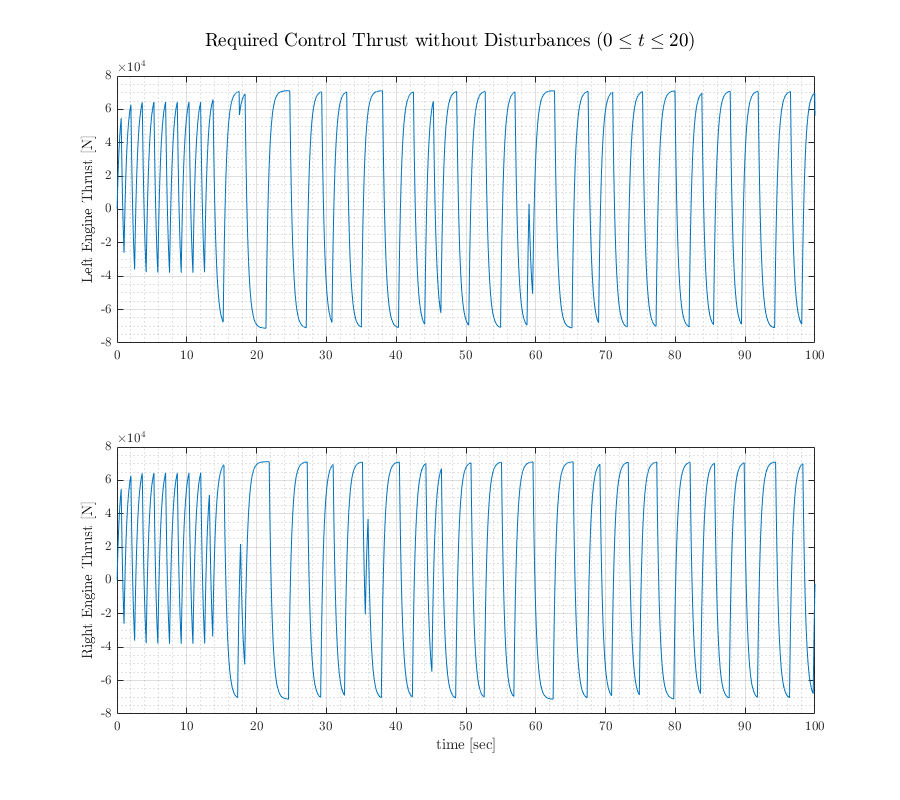

% Plot Thrust
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    subplot(2,1,1)
    plot(t, res.Doff.Fl)
    grid on; grid minor; box on;
    ylabel('Left Engine Thrust [N]')
    subplot(2,1,2)
    plot(t, res.Doff.Fr)
    grid on; grid minor; box on;
    ylabel('Right Engine Thrust [N]')
    xlabel('time [sec]')
    title_string = 'Required Control Thrust without Disturbances ($0\leq t \leq 100$)';
    sgtitle(title_string)

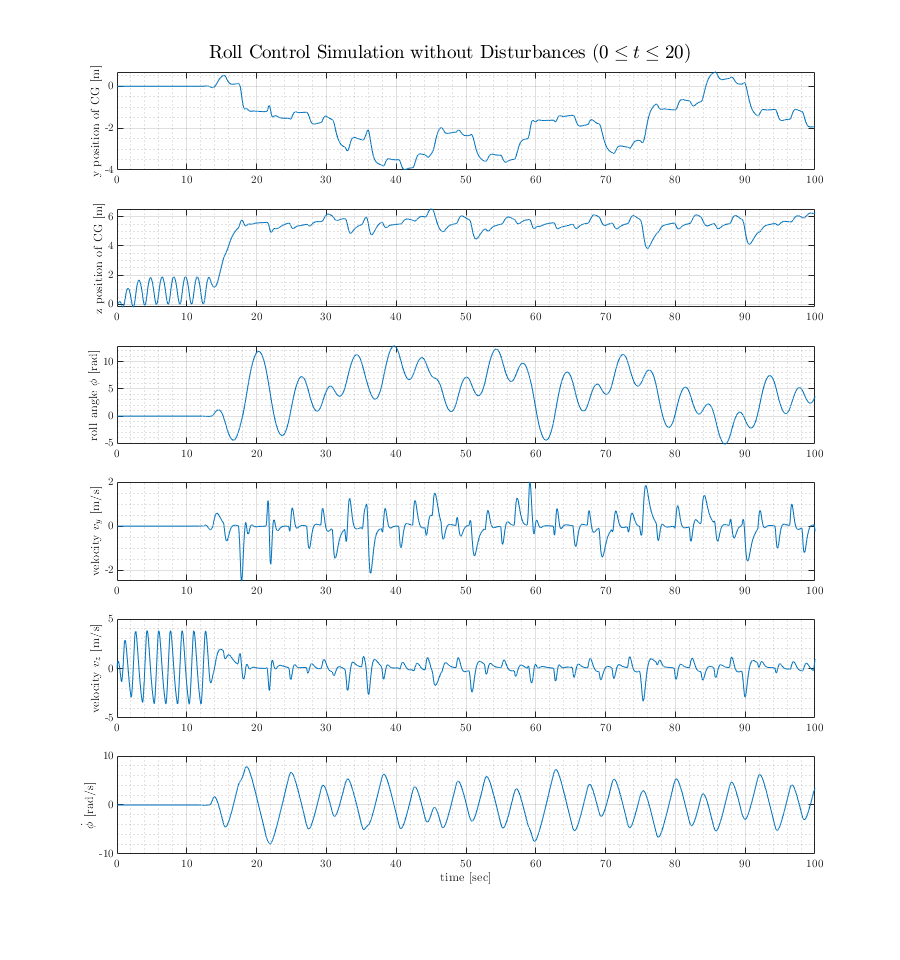

% Plot Thrust
fig = figure("Renderer","painters","Position",[60 60 900 960]);
    subplot(6,1,1)
    plot(t, res.Doff.y)
    grid on; grid minor; box on;
    ylabel('y position of CG [m]')
    subplot(6,1,2)
    plot(t, res.Doff.z)
    grid on; grid minor; box on;
    ylabel('z position of CG [m]')
    subplot(6,1,3)
    plot(t, res.Doff.phi)
    grid on; grid minor; box on;
    ylabel('roll angle $\phi$ [rad]')
    subplot(6,1,4)
    plot(t, res.Doff.ydot)
    grid on; grid minor; box on;
    ylabel('velocity $v_y$ [m/s]')
    subplot(6,1,5)
    plot(t, res.Doff.zdot)
    grid on; grid minor; box on;
    ylabel('velocity $v_z$ [m/s]')
    subplot(6,1,6)
    plot(t, res.Doff.phidot)
    grid on; grid minor; box on;
    ylabel('$\dot{\phi}$ [rad/s]')
    xlabel('time [sec]')
    title_string = 'Roll Control Simulation without Disturbances ($0\leq t \leq 100$)';
    sgtitle(title_string)

### Simulate with disturbance

noise_on = 1;  % turn on/off noise
disturbance_on = 1;  % turn on/off disturbance
simout = sim("vtol_roll_v2.slx");  % Run simulation 

% Obtain values from simulation
t = simout.tout;  % time span
res.Don.Fl = simout.Fleft.signals.values;  % Thrust from left engine
res.Don.Fr = simout.Fright.signals.values;  % Thrust from right engine
res.Don.y = simout.xstates.signals.values(:,1);  % y values
res.Don.z = simout.xstates.signals.values(:,2);  % z values
res.Don.phi = simout.xstates.signals.values(:,3);  % phi values
res.Don.ydot = simout.xstates.signals.values(:,4);  % ydot values
res.Don.zdot = simout.xstates.signals.values(:,5);  % zdot values
res.Don.phidot = simout.xstates.signals.values(:,6);  % phidot values 

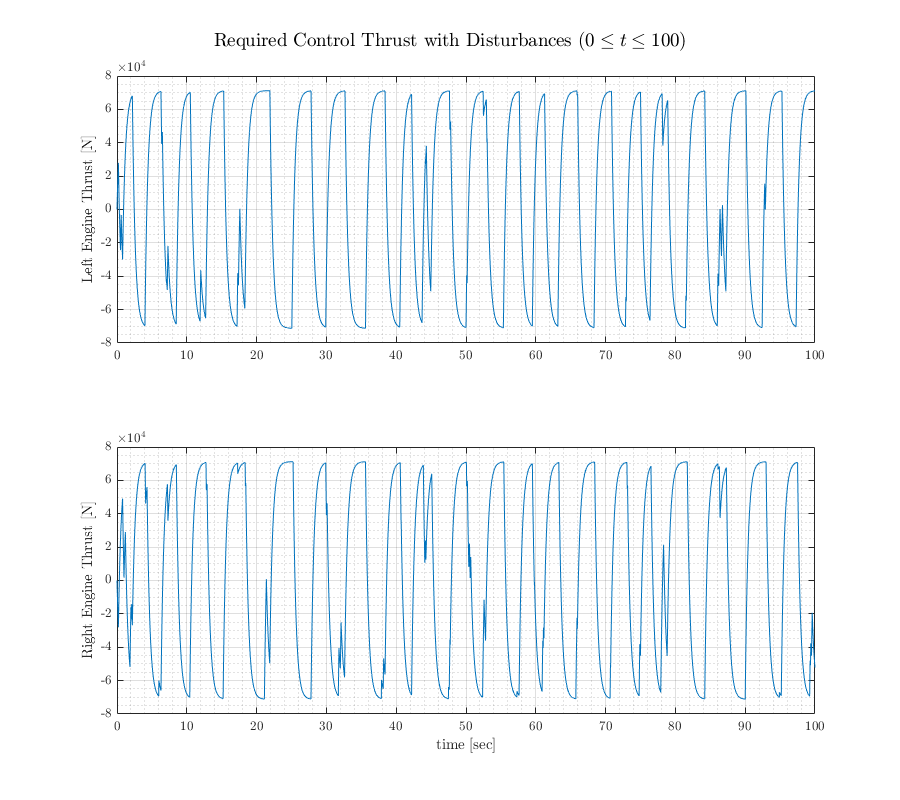

% Plot Thrust
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    subplot(2,1,1)
    plot(t, res.Don.Fl)
    grid on; grid minor; box on;
    ylabel('Left Engine Thrust [N]')
    subplot(2,1,2)
    plot(t, res.Don.Fr)
    grid on; grid minor; box on;
    ylabel('Right Engine Thrust [N]')
    xlabel('time [sec]')
    title_string = 'Required Control Thrust with Disturbances ($0\leq t \leq 100$)';
    sgtitle(title_string)

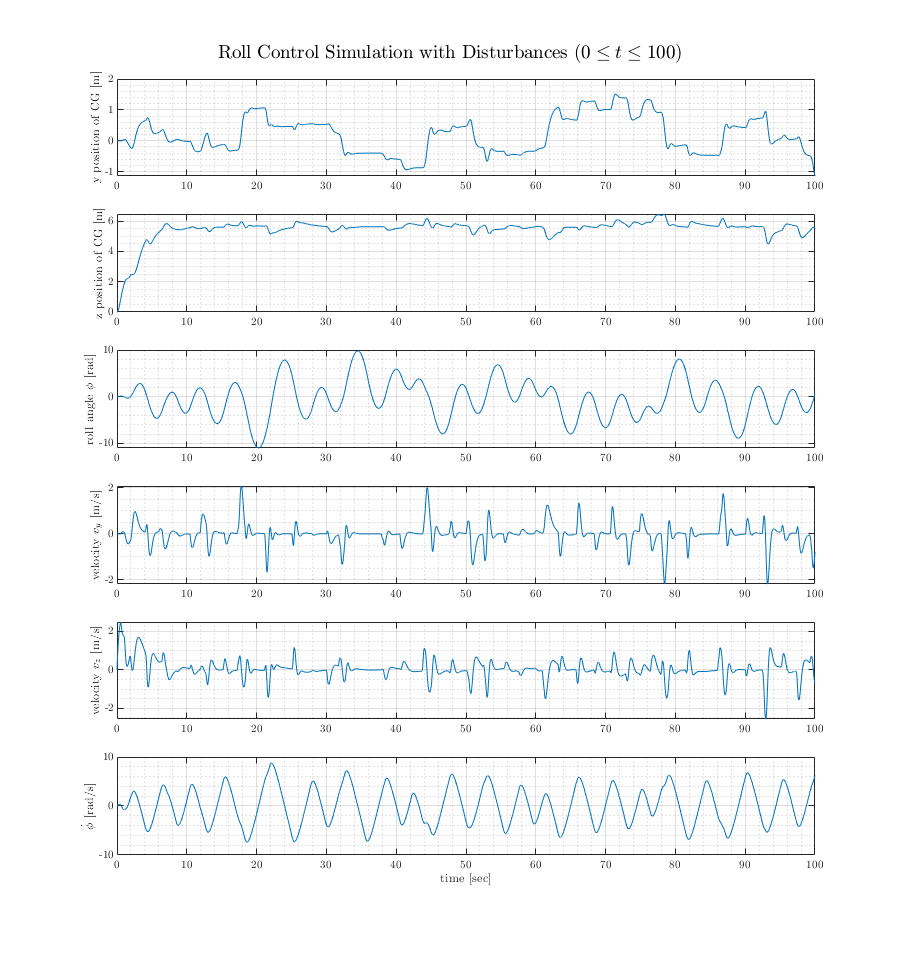

% Plot Thrust
fig = figure("Renderer","painters","Position",[60 60 900 960]);
    subplot(6,1,1)
    plot(t, res.Don.y)
    grid on; grid minor; box on;
    ylabel('y position of CG [m]')
    subplot(6,1,2)
    plot(t, res.Don.z)
    grid on; grid minor; box on;
    ylabel('z position of CG [m]')
    subplot(6,1,3)
    plot(t, res.Don.phi)
    grid on; grid minor; box on;
    ylabel('roll angle $\phi$ [rad]')
    subplot(6,1,4)
    plot(t, res.Don.ydot)
    grid on; grid minor; box on;
    ylabel('velocity $v_y$ [m/s]')
    subplot(6,1,5)
    plot(t, res.Don.zdot)
    grid on; grid minor; box on;
    ylabel('velocity $v_z$ [m/s]')
    subplot(6,1,6)
    plot(t, res.Don.phidot)
    grid on; grid minor; box on;
    ylabel('$\dot{\phi}$ [rad/s]')
    xlabel('time [sec]')
    title_string = 'Roll Control Simulation with Disturbances ($0\leq t \leq 100$)';
    sgtitle(title_string)

## References

[1] Feng Lin, W. Zhang and R. D. Brandt, "Robust hovering control of a PVTOL aircraft," in IEEE Transactions on Control Systems Technology, vol. 7, no. 3, pp. 343-351, May 1999, doi: 10.1109/87.761054.

[2] Martin Corless, "AAE 666 Notes," School of Aeronautical and Astronautical Engineering, Purdue University, January 2021. 

[3] Prasad, L.B., Tyagi, B. & Gupta, H.O. Optimal Control of Nonlinear Inverted Pendulum System Using PID Controller and LQR: Performance Analysis Without and With Disturbance Input. *Int. J. Autom. Comput.* 11**, **661–670 (2014). [https://doi.org/10.1007/s11633-014-0818-1](https://doi.org/10.1007/s11633-014-0818-1)

[4] “Evaluation of Global Wind Power.” *Global Wind Power at 80 m*, Stanford University , web.stanford.edu/group/efmh/winds/global_winds.html. 

[5] Rehmatulla, Nishatabbas & Parker, Sophia & Smith, Tristan & Stulgis, Victoria. (2015). Wind technologies: Opportunities and barriers to a low carbon shipping industry. Marine Policy. 75. 10.1016/j.marpol.2015.12.021. 

[6] Steve Brunton. (2017, February 6). *Control Bootcamp: LQG Example in Matlab* [Video]. YouTube. https://www.youtube.com/watch?v=reRT8LbPhBs